Homework 2 - Abhinav Brahmarouthu

1) Rolling a seven is more likely than rolling snake eyes when using 2 fair 6-sided dice. The probability of rolling snake eyes is equal to the probability of rolling a 1 twice in a row:$P(snake eyes) = P(1) * P(1)  = 1/6 + 1/6 = \frac{1}{36}$ 

Meanwhile, a seven can be rolled 6 different ways; 1 and 6, 2 and 5, 3 and 4, and the reverse ways too. Each combination has a probability of 1/6, so combined this is $6/36 = 1/6$ . As a ratio of probabilities: $$\frac{P(7)}{P(1)} = \frac{1/6}{1/36} = 6$ $, therefore rolling a 7 is 6 times more likley than rolling snake eyes. 

2) The probability of the sum of two dice can be found by the convolution of the probability functions for each dice. Since the outcome of a die is a discrete scenario, a convolution sum must be used instead of a convolution integral. Let $x$ be the sum of two dice and $P(x)$ be the probability of a sum of x, and $P_1(z)$ be the probability of rolling $z$. Then the convolution sum is: $P\left(x\right)=\sum_{z=1}^6 P_1 \left(z\right)P_1 \left(x-z\right)$

Here is code that computes the probability of dice rolls using the convolution sum:

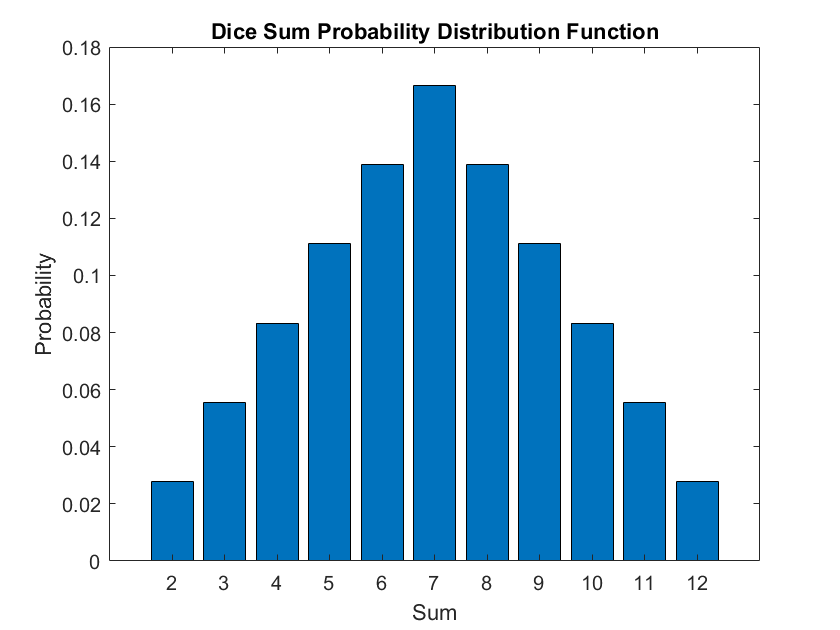

%perform the convolution sum of two dice:
probability = zeros(1,11);
sum = 2:12;
for k = 2:12
    for i = 1:6    %Possibilities for die 1
        for j = 1:6 %Possibilities for die 2
            if (i + j) == sum(k-1)   %Check if sucess
                probability(k-1) = probability(k-1) + (1/36); %Probability of any permutation is 1/36
            end
        end
    end
end

figure
bar(2:12, probability)
title('Dice Sum Probability Distribution Function')
xlabel('Sum')
ylabel('Probability')

3) Calculating the mean and standard deviation. To calculate the mean I will simply take the sum: $M=\frac{\sum_{n=2}^{12} P\left(n\right)*n}{1}$. The standard deviation is a bit more complicated because it must be wighted by the probability of each sum $S=\sqrt{\frac{\sum_2^{12} {P\left(x\right)\left(M-x\right)}^2 }{1}}$Notice that the probability itself must not be squared.

%initializing variables
mean = 0;
stdev = 0;

%calculating mean
for i = 1:11
    mean = mean + probability(i)*(i+1);
end

%calculating standard deviation
for i = 1:11
    stdev = stdev + (probability(i)*(mean - (i+1)).^2);
end
mean

mean = 7

stdev = sqrt(stdev)

stdev = 2.4152

4) Now for the sum of 10 dice:

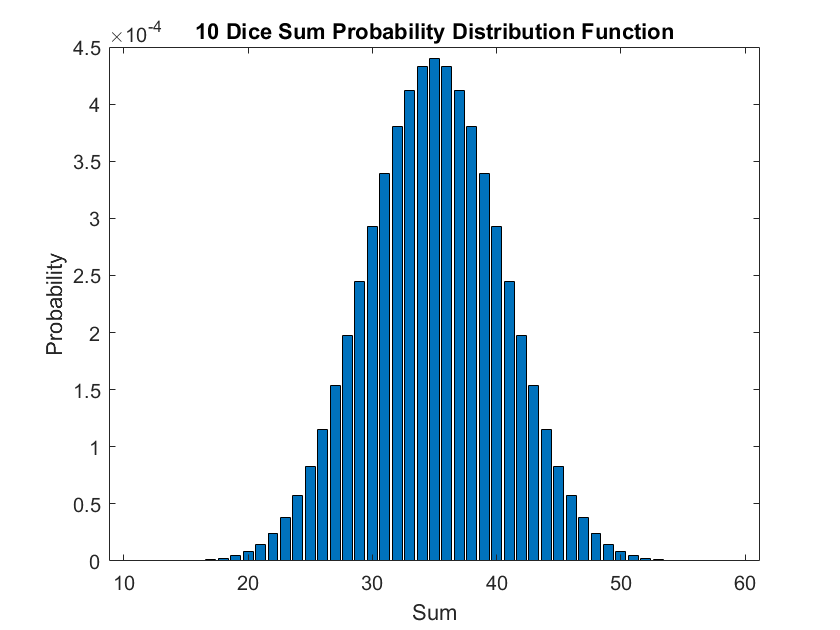

%perform the convolution sum of two dice:
probability = zeros(1,51);
sum = 10:60;

for k = 10:60;
for i1 = 1:6
    for i2 = 1:6
        for i3 = 1:6
            for i4 = 1:6
                for i5 = 1:6
                    for i6 = 1:6
                        for i7 = 1:6
                            for i8 = 1:6
                                for i9 = 1:6
                                    for i10 = 1:6
                                        sum = i1+i2+i3+i4+i5+i6+i7+i8+i9+i10;
                                        if sum == k
                                            probability(k-9) = probability(k-9) + (1/((10)^(10)));
                                        end
                                    end
                                end
                            end
                        end
                    end
                end
            end
        end
    end
end
end

figure
bar(10:60, probability)
title('10 Dice Sum Probability Distribution Function')
xlabel('Sum')
ylabel('Probability')

This is cannot be a Gaussian distribution because the sum is a discrete variable and Gaussian distribution is by definition continuous. It does however seem to take on the shape of a gaussian distribution due to the central limit theorem. Whenever any type of random distribution is sampled large enough it will begin to look like a normal distribution at some point.